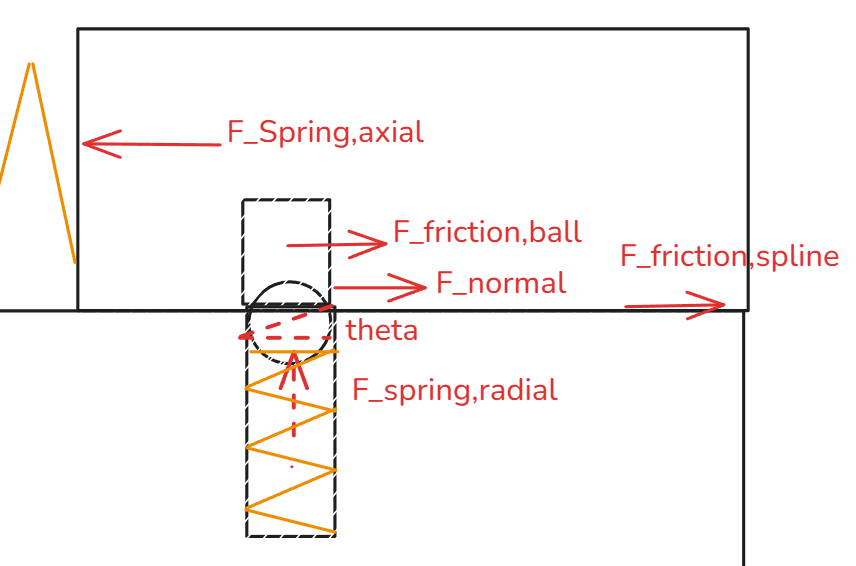

clear
g = 9.82;
m_spline = 1; %kg
f_s = 0.35;

k_axial = 0.29; % N/mm % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000


% F_spring_radial = 174;
k_radial = 12.16; % N/mm %max compresion 13.80, total length 27.00; max force 169,66
% varenummer 12410
x_radial = 3; % mm compressed spring to hold
F_spring_radial = k_radial*x_radial

F_spring_radial = 36.4800



syms F_n %F_spring_radial

theta = 20; %angle on ball lock
F_spline_fric = g * m_spline * f_s

F_spline_fric = 3.4370


F_ball_fric = sind(theta) * F_spring_radial * f_s;



F_x_eq = 0 == F_spring_axial - F_ball_fric - F_spline_fric - F_n * cosd(theta); %  F_spline_fric


F_n_y = F_spring_axial * sind(theta)

F_n_y = 13.8860

F_y_eq = 0 == F_n * sind(theta) - F_spring_radial;

F_n_sol = solve(F_x_eq, F_n);
% [F_n_sol, F_spring_radial_sol] = solve([F_x_eq, F_y_eq], [F_n, F_spring_radial]);
F_n = double(F_n_sol)

F_n = 34.9009

% F_spring_radial = double(F_spring_radial_sol)

% F_spring1_x = F_spring_axial * cosd(phi)
% F_spring_axial_y = F_spring_axial * sind(phi)


phi = 45

phi = 45



F_realese = 553; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
% tallerken fjeder vare nummer 1800-620-70

F_realease_x = sind(phi) * F_realese

F_realease_x = 391.0300

F_realese_ball = F_realease_x / cos(theta)

F_realese_ball = 958.2143

F_realease_ball_y = sind(theta) * F_realese_ball

F_realease_ball_y = 327.7286

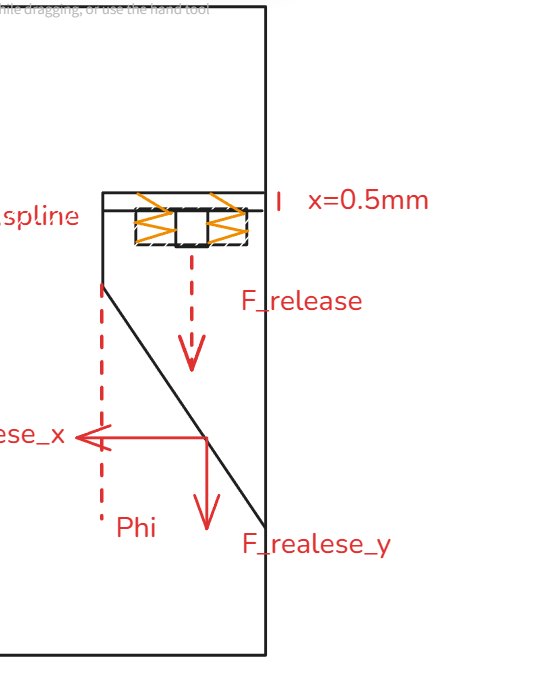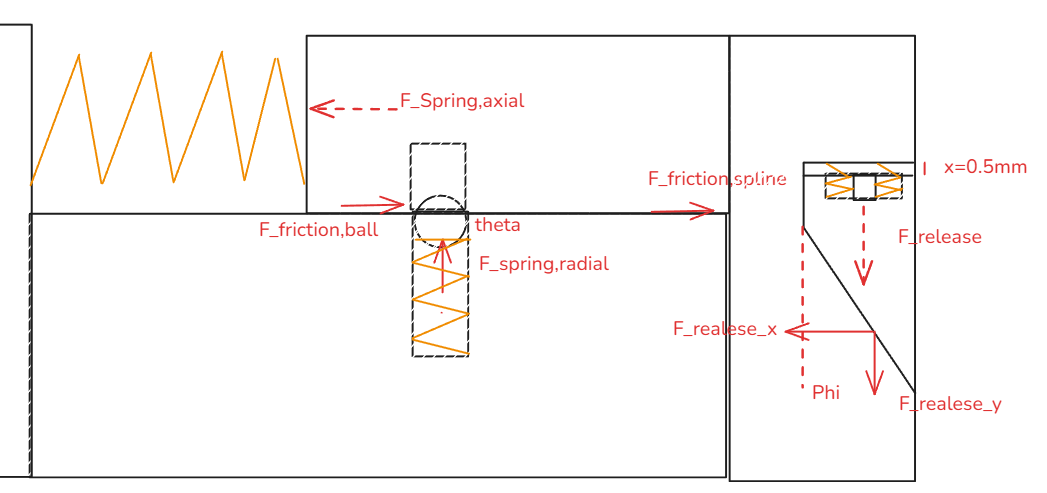

syms a
eq_x_dyn = m_spline * a == F_spring_radial - F_spline_fric - F_ball_fric

$$eq\_x\_dyn = a=\frac{8071600867002529}{281474976710656}$$


a = double(solve(eq_x_dyn, a))

a = 28.6761


r = 0.1;
s = 0.53e-3;
T = F_realese * r

T = 55.3000


W = F_realese * s

W = 0.2931


syms omega
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
I = 15.9356; % inertia of the test motor % HMC4 355L-2
W_eq = W == 1/2 * I * omega^2;
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.1918

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse

limits for pulling and pushing [https://www.ccohs.ca/oshanswers/ergonomics/push1.html](https://www.ccohs.ca/oshanswers/ergonomics/push1.html)